## A: Now, with drive+LDE

### A1. Prepair parameters for drive simulation

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_S = zeros(size(NnS.X),'single');
OD_SMap = zeros(n_S_HC*N_HC,'single');
for NeuInd = 1:length(NnS.X)
    OD_S(NeuInd) = OrientDom(ODNum,NnS.X(NeuInd),NnS.Y(NeuInd),n_S_HC);
    OD_SMap(NnS.Y(NeuInd),NnS.X(NeuInd)) = OD_S(NeuInd);
end

OD_C = zeros(size(NnC.X),'single');
OD_CMap = zeros(n_C_HC*N_HC,'single');
for NeuInd = 1:length(NnC.X)
    OD_C(NeuInd) = OrientDom(ODNum,NnC.X(NeuInd),NnC.Y(NeuInd),n_C_HC);
    OD_CMap(NnC.Y(NeuInd),NnC.X(NeuInd)) = OD_C(NeuInd);
end
OD_E = [OD_S, OD_C];

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
    OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
    OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 4; % 2 4 10Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
%PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Slgn/1e3 * StimulusFac; % 4 to 5

Grating = 0; % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
PhaseFRS_Grating = [45+abs(mod(GratingHC,180)-90)/2,45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;%PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Clgn/1e3 * StimulusFac;
PhaseFRC = 45*ones(1,8) *N_Clgn/1e3 * StimulusFac;
lambda_EOn_drive  = [PhaseFRS_Grating(OD_S),PhaseFRC(OD_C)]'; % Should do another for Cplx cells
lambda_EOff_drive = [PhaseFRS_Grating(OD_S+ODNum),PhaseFRC(OD_C+ODNum)]';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

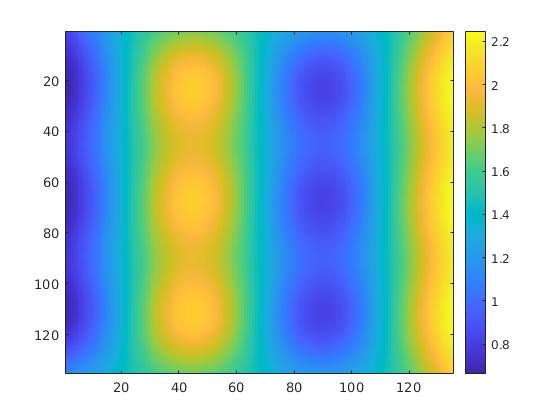

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive_Pre = 45 *N_Slgn/1e3 * StimulusFac;
lambda_I_drive_Pre = 45 *N_Ilgn/1e3 * StimulusFac;

% Ver1
% L6Ord_F = [50 33 15 33];
% Ver 4
L6Ord_F = [54 32 10 32];
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
L6S_Drive = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;
L6C_Drive = L6Ord_F_Grating*NC_L6/1e3 * StimulusFac;
L6I_Drive = L6Ord_F_Grating*NI_L6/1e3 * StimulusFac;

% NOTE: Doing Gaussian blur
FigOn = true;
sig = 0.3;% of HC
L6SFilt = SpatialGaussianFilt(OD_SMap,L6S_Drive,n_S_HC*sig,FigOn);

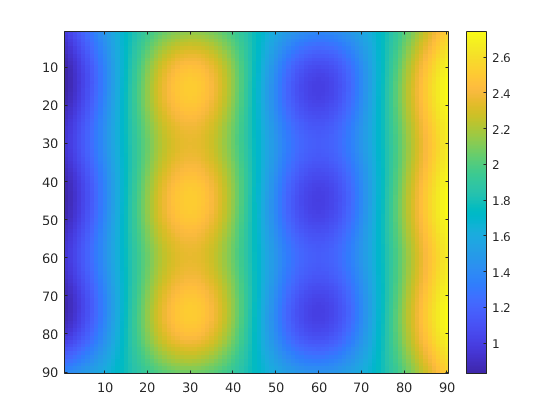

L6CFilt = SpatialGaussianFilt(OD_CMap,L6C_Drive,n_C_HC*sig,FigOn);

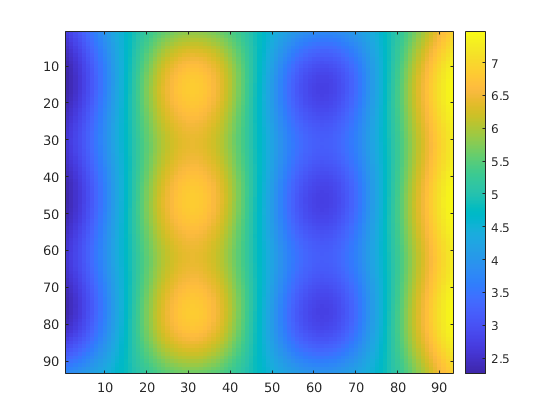

L6IFilt = SpatialGaussianFilt(OD_IMap,L6I_Drive,n_I_HC*sig,FigOn);


rE_L6_Drive = [L6SFilt;L6CFilt];
rI_L6_Drive = L6IFilt;


% Making Poisson here/Reading
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

### A2. Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
% SimulationT = 5000;
% E-to-E delay time
T_EEDly = .1; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .1; N_IEDly = floor(T_IEDly/dt); %% NOTE: Was both 0.5
T_EIDly = .1; N_EIDly = floor(T_EIDly/dt);
% The initial states, for more simulation
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
Fields = {'RefTimeE','VE','SpE','GE_ampa_R','GE_nmda_R','GE_gaba_R','GE_ampa_D','GE_nmda_D','GE_gaba_D',...
    'RefTimeI','VI','SpI','GI_ampa_R','GI_nmda_R','GI_gaba_R','GI_ampa_D','GI_nmda_D','GI_gaba_D'};
InSStr = cell2struct(EndState(1:length(Fields)), Fields, 2);
[InEs, InIs] = LargeNW_LoadIniState('InSStr', InSStr,N_E, N_I);
RefTimeE = InEs.RefTimeE; VE = InEs.VE; SpE = InEs.SpE; GE_ampa_R = InEs.GE_ampa_R; GE_nmda_R = InEs.GE_nmda_R; GE_gaba_R = InEs.GE_gaba_R;
GE_ampa_D = InEs.GE_ampa_D; GE_nmda_D = InEs.GE_nmda_D; GE_gaba_D = InEs.GE_gaba_D;
RefTimeI = InIs.RefTimeI; VI = InIs.VI; SpI = InIs.SpI; GI_ampa_R = InIs.GI_ampa_R; GI_nmda_R = InIs.GI_nmda_R; GI_gaba_R = InIs.GI_gaba_R;
GI_ampa_D = InIs.GI_ampa_D; GI_nmda_D = InIs.GI_nmda_D; GI_gaba_D = InIs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = ones(N_I,N_IEDly);
EIDlyRcd = ones(N_E,N_EIDly);
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))];
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))];
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end

% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
% SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
    'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
    'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
    'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

Bug here: Though I defined AdjlgnE for every step, it is used only every 100ms...

So: 250on/250off are mixed here...

for TSec = 1:TPar
    tic
    for TimeN = 1:floor(T/dt/TPar)
        % Zero: Use Phase vec to determine different lgn phases for E neurons
        PhaseE = mod(PhaseE + dt,tMod);
        % First, Get input matrices from series
        InpWin = 100; FrameNum = floor(InpWin/dt);
        FrameInd = mod(TimeN, FrameNum);
        if FrameInd == 0
            FrameInd = FrameNum;
        end
        RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
        if FrameInd  == 1 % if the first frame, recompute input mats
            tt = 0:dt:InpWin-dt;
            AdjlgnE = PhaseFRS_Grating(floor(mod(PhaseE + tt, tMod)/MaxOnPhase)*ODNum + OD_E');
            AdjlgnE(EcplxInd,:) = PhaseFRC(floor(mod(PhaseE(EcplxInd) + tt, tMod)/MaxOnPhase)*ODNum + OD_E(EcplxInd)');
            EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE/lambda_E_drive_Pre + AdjlgnE*dt*LGNCurInp)...
                + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
            IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive_Pre*dt*LGNCurInp) ...
                + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa

            EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); %
            InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));

        end


        %      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
        %      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
        %      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
        [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
            oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
            oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
            oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
            oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
            V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
            GE_ampa_D,GE_nmda_D,GE_gaba_D,...
            RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
            GI_ampa_D,GI_nmda_D,GI_gaba_D,...
            EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
            C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
            S_EE,S_EI,S_IE,S_II,...
            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
            dt,p_EEFail,...
            gL_E,Ve,rhoE_ampa,rhoE_nmda,...
            gL_I,Vi,rhoI_ampa,rhoI_nmda,...
            EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
            EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
        % iteration
        RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
        GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
        RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
        GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
        EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;

        % Record Every Time time window
        RecordNum = floor(sampleT/dt);
        RecordInd = mod(TimeN, RecordNum);
        SampleRate = 0.1; % Can't be too small for multiple phases
        if RecordInd == 1
            clear E_Sp I_Sp mVETemp mVITemp
            E_Sp = [];
            I_Sp = [];
            mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
            mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
            GE_ETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
            GE_ITemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
            GI_ETemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
            GI_ITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
            mVRecordInd = 1;
        elseif RecordInd == 0
            NWTrace(SampleInd).mVEs = mVETemp;
            NWTrace(SampleInd).mVIs = mVITemp;

            NWTrace(SampleInd).SpEs = E_Sp;
            NWTrace(SampleInd).SpIs = I_Sp;

            NWTrace(SampleInd).GE_I = GE_ITemp;
            NWTrace(SampleInd).GE_E = GE_ETemp;
            NWTrace(SampleInd).GI_I = GI_ITemp;
            NWTrace(SampleInd).GI_E = GI_ETemp;
            SampleInd = SampleInd + 1
            %sum(isnan(oVE))/N_E
            FrESNow = sum(ismember(E_Sp(:,1), find(~EcplxInd)))/N_S/sampleT*1000
            FrECNow = sum(ismember(E_Sp(:,1), find(EcplxInd)))/N_C/sampleT*1000
            FrINow = size(I_Sp,1)/N_I/sampleT*1000
            toc
        end
        E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
        I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);

        if mod(TimeN,floor(1/SampleRate)) == 5
            mVETemp(:,mVRecordInd) = oVE;
            mVITemp(:,mVRecordInd) = oVI;
            % Precompute GE GI
            GE_I = 1/(tau_gaba_D-tau_gaba_R) * (GE_gaba_D - GE_gaba_R); % S_EI is included in amplitude of GE_gaba
            GE_E = 1/(tau_ampa_D-tau_ampa_R) * (GE_ampa_D - GE_ampa_R) + ...
                1/(tau_nmda_D-tau_nmda_R) * (GE_nmda_D - GE_nmda_R); %

            GI_I = 1/(tau_gaba_D-tau_gaba_R) * (GI_gaba_D - GI_gaba_R); % S_EI is included in amplitude of GE_gaba
            GI_E = 1/(tau_ampa_D-tau_ampa_R) * (GI_ampa_D - GI_ampa_R) + ...
                1/(tau_nmda_D-tau_nmda_R) * (GI_nmda_D - GI_nmda_R); %
            GE_ITemp(:,mVRecordInd) = GE_I;
            GE_ETemp(:,mVRecordInd) = GE_E;
            GI_ITemp(:,mVRecordInd) = GI_I;
            GI_ETemp(:,mVRecordInd) = GI_E;
            %record loop goes forward
            mVRecordInd = mVRecordInd + 1;
        end

        if sum(isnan(oVE))>0.80*N_E
            BlowUp = true;
            disp('warning!: Network exploded')
            break
        end

        % the end of iteration
    end
    toc
    text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz_Deg%.1f_',LGNFreq,Grating) ...
            num2str(TSec) 's.mat'];
    EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
        RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
        EEDlyRcd, IEDlyRcd};
    save([SaveFolder text],'NWTrace','EndState','PhaseE','-v7.3')

    clear NWTrace
    NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
        'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
        'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
        'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
end

SampleInd = 2

FrESNow = 8.2601

FrECNow = 9.9827

FrINow = 41.3134

Elapsed time is 2.042812 seconds.


SampleInd = 3

FrESNow = 9.6702

FrECNow = 25.5037

FrINow = 53.8744

Elapsed time is 3.551554 seconds.


SampleInd = 4

FrESNow = 8.9372

FrECNow = 23.9235

FrINow = 51.8465

Elapsed time is 5.757427 seconds.


SampleInd = 5

FrESNow = 9.0853

FrECNow = 29.1235

FrINow = 56.3672

Elapsed time is 7.203576 seconds.


SampleInd = 6

FrESNow = 8.6804

FrECNow = 21.9086

FrINow = 51.3770

Elapsed time is 9.356017 seconds.


SampleInd = 7

FrESNow = 9.0063

FrECNow = 26.7926

FrINow = 54.8433

Elapsed time is 10.766276 seconds.


SampleInd = 8

FrESNow = 8.8187

FrECNow = 28.3111

FrINow = 56.4458

Elapsed time is 12.939007 seconds.


SampleInd = 9

FrESNow = 8.6288

FrECNow = 25.4840

FrINow = 53.8629

Elapsed time is 14.333316 seconds.


SampleInd = 10

FrESNow = 8.8318

FrECNow = 26.6963

FrINow = 55.2226

Elapsed time is 16.503911 seconds.


SampleInd = 11

FrESNow = 8.5344

FrECNow = 26.7580

FrINow = 54.7277

Elapsed time is 17.904188 seconds.


SampleInd = 12

FrESNow = 8.4938

FrECNow = 26.9210

FrINow = 54.5080

Elapsed time is 20.014792 seconds.


SampleInd = 13

FrESNow = 9.1281

FrECNow = 28.7827

FrINow = 56.6956

Elapsed time is 21.478025 seconds.


SampleInd = 14

FrESNow = 8.6738

FrECNow = 25.1358

FrINow = 53.8051

Elapsed time is 23.559451 seconds.


SampleInd = 15

FrESNow = 8.7956

FrECNow = 28.8667

FrINow = 56.3811

Elapsed time is 25.035482 seconds.


SampleInd = 16

FrESNow = 8.9723

FrECNow = 29.0765

FrINow = 56.8366

Elapsed time is 27.209432 seconds.


SampleInd = 17

FrESNow = 8.3556

FrECNow = 22.2296

FrINow = 51.1990

Elapsed time is 28.617256 seconds.


SampleInd = 18

FrESNow = 8.9635

FrECNow = 27.4346

FrINow = 55.1023

Elapsed time is 30.753679 seconds.


SampleInd = 19

FrESNow = 8.8878

FrECNow = 27.2222

FrINow = 55.6064

Elapsed time is 32.223067 seconds.


SampleInd = 20

FrESNow = 8.8044

FrECNow = 29.0321

FrINow = 56.2817

Elapsed time is 34.423497 seconds.


SampleInd = 21

FrESNow = 8.7133

FrECNow = 23.0642

FrINow = 52.6373

Elapsed time is 35.843613 seconds.


Elapsed time is 35.844444 seconds.


SampleInd = 22

FrESNow = 8.9218

FrECNow = 28.2864

FrINow = 56.0157

Elapsed time is 2.138047 seconds.


SampleInd = 23

FrESNow = 8.9339

FrECNow = 27.7506

FrINow = 56.0435

Elapsed time is 3.654496 seconds.


SampleInd = 24

FrESNow = 8.6167

FrECNow = 24.9432

FrINow = 53.7611

Elapsed time is 5.712402 seconds.


SampleInd = 25

FrESNow = 8.0889

FrECNow = 25.1210

FrINow = 52.9472

Elapsed time is 7.059811 seconds.


SampleInd = 26

FrESNow = 9.2401

FrECNow = 30.2370

FrINow = 57.8055

Elapsed time is 9.174634 seconds.


SampleInd = 27

FrESNow = 8.7912

FrECNow = 26.7235

FrINow = 55.3567

Elapsed time is 10.569265 seconds.


SampleInd = 28

FrESNow = 8.4785

FrECNow = 24.4988

FrINow = 53.1599

Elapsed time is 12.652482 seconds.


SampleInd = 29

FrESNow = 8.6892

FrECNow = 28.5975

FrINow = 56.1498

Elapsed time is 14.159592 seconds.


SampleInd = 30

FrESNow = 8.8713

FrECNow = 26.2173

FrINow = 54.8110

Elapsed time is 16.249531 seconds.


SampleInd = 31

FrESNow = 8.9997

FrECNow = 28.8099

FrINow = 56.5545

Elapsed time is 17.731147 seconds.


SampleInd = 32

FrESNow = 8.9438

FrECNow = 26.5012

FrINow = 55.1648

Elapsed time is 19.812186 seconds.


SampleInd = 33

FrESNow = 8.4203

FrECNow = 25.4815

FrINow = 53.8120

Elapsed time is 21.206489 seconds.


SampleInd = 34

FrESNow = 8.6376

FrECNow = 25.8198

FrINow = 53.9531

Elapsed time is 23.305321 seconds.


SampleInd = 35

FrESNow = 8.8713

FrECNow = 29.2593

FrINow = 56.4851

Elapsed time is 24.742293 seconds.


SampleInd = 36

FrESNow = 8.8669

FrECNow = 26.5605

FrINow = 55.0353

Elapsed time is 26.851624 seconds.


SampleInd = 37

FrESNow = 8.5838

FrECNow = 25.3037

FrINow = 53.7843

Elapsed time is 28.256559 seconds.


SampleInd = 38

FrESNow = 8.4752

FrECNow = 25.4198

FrINow = 53.7773

Elapsed time is 30.379928 seconds.


SampleInd = 39

FrESNow = 8.8472

FrECNow = 27.0938

FrINow = 55.2549

Elapsed time is 31.844585 seconds.


SampleInd = 40

FrESNow = 9.0425

FrECNow = 29.7062

FrINow = 57.3962

Elapsed time is 34.013646 seconds.


SampleInd = 41

FrESNow = 8.8658

FrECNow = 28.4840

FrINow = 56.5198

Elapsed time is 35.564645 seconds.


Elapsed time is 35.565406 seconds.


SampleInd = 42

FrESNow = 8.3665

FrECNow = 23.1333

FrINow = 51.9713

Elapsed time is 2.031146 seconds.


SampleInd = 43

FrESNow = 8.9690

FrECNow = 27.8395

FrINow = 56.2262

Elapsed time is 3.439355 seconds.


SampleInd = 44

FrESNow = 8.7660

FrECNow = 27.5926

FrINow = 55.5856

Elapsed time is 5.554683 seconds.


SampleInd = 45

FrESNow = 8.3402

FrECNow = 23.3926

FrINow = 51.5065

Elapsed time is 6.895729 seconds.


SampleInd = 46

FrESNow = 9.0974

FrECNow = 26.9284

FrINow = 55.6064

Elapsed time is 8.964596 seconds.


SampleInd = 47

FrESNow = 8.8911

FrECNow = 27.5506

FrINow = 55.3359

Elapsed time is 10.372528 seconds.


SampleInd = 48

FrESNow = 8.8845

FrECNow = 29.0963

FrINow = 56.9731

Elapsed time is 12.458346 seconds.


SampleInd = 49

FrESNow = 8.2875

FrECNow = 23.0914

FrINow = 51.7979

Elapsed time is 13.865379 seconds.


SampleInd = 50

FrESNow = 9.1435

FrECNow = 28.2099

FrINow = 56.3233

Elapsed time is 16.061735 seconds.


SampleInd = 51

FrESNow = 8.6321

FrECNow = 26.0049

FrINow = 54.3508

Elapsed time is 17.503818 seconds.


SampleInd = 52

FrESNow = 8.8110

FrECNow = 25.6593

FrINow = 54.0224

Elapsed time is 19.662669 seconds.


SampleInd = 53

FrESNow = 8.8055

FrECNow = 26.9457

FrINow = 55.0260

Elapsed time is 21.131674 seconds.


SampleInd = 54

FrESNow = 8.8856

FrECNow = 26.8914

FrINow = 55.0561

Elapsed time is 23.225771 seconds.


SampleInd = 55

FrESNow = 9.1358

FrECNow = 30.3531

FrINow = 57.7246

Elapsed time is 24.723233 seconds.


SampleInd = 56

FrESNow = 8.7155

FrECNow = 25.3086

FrINow = 54.0247

Elapsed time is 26.828992 seconds.


SampleInd = 57

FrESNow = 8.8318

FrECNow = 27.7136

FrINow = 55.6943

Elapsed time is 28.280110 seconds.


SampleInd = 58

FrESNow = 8.6167

FrECNow = 27.2000

FrINow = 55.4654

Elapsed time is 30.405569 seconds.


SampleInd = 59

FrESNow = 8.5586

FrECNow = 20.8370

FrINow = 50.3896

Elapsed time is 31.742941 seconds.


SampleInd = 60

FrESNow = 9.1808

FrECNow = 33.0444

FrINow = 59.7757

Elapsed time is 33.909791 seconds.


SampleInd = 61

FrESNow = 8.7638

FrECNow = 28.0519

FrINow = 55.6989

Elapsed time is 35.314840 seconds.


Elapsed time is 35.315602 seconds.


SampleInd = 62

FrESNow = 8.5432

FrECNow = 24.0519

FrINow = 53.1923

Elapsed time is 2.096624 seconds.


SampleInd = 63

FrESNow = 8.7682

FrECNow = 26.7407

FrINow = 54.9381

Elapsed time is 3.538060 seconds.


SampleInd = 64

FrESNow = 8.7791

FrECNow = 24.2395

FrINow = 53.0859

Elapsed time is 5.608382 seconds.


SampleInd = 65

FrESNow = 9.3937

FrECNow = 32.7827

FrINow = 59.7780

Elapsed time is 7.123813 seconds.


SampleInd = 66

FrESNow = 8.4774

FrECNow = 23.2025

FrINow = 52.4639

Elapsed time is 9.178551 seconds.


SampleInd = 67

FrESNow = 8.9920

FrECNow = 30.8519

FrINow = 58.0923

Elapsed time is 10.649965 seconds.


SampleInd = 68

FrESNow = 8.0735

FrECNow = 21.2593

FrINow = 50.4035

Elapsed time is 12.661839 seconds.


SampleInd = 69

FrESNow = 8.8845

FrECNow = 26.3580

FrINow = 54.4895

Elapsed time is 14.059580 seconds.


SampleInd = 70

FrESNow = 8.6672

FrECNow = 27.1926

FrINow = 55.2203

Elapsed time is 16.146085 seconds.


SampleInd = 71

FrESNow = 8.9174

FrECNow = 27.3407

FrINow = 55.3382

Elapsed time is 17.628370 seconds.


SampleInd = 72

FrESNow = 8.8746

FrECNow = 28.4272

FrINow = 56.3163

Elapsed time is 19.739442 seconds.


SampleInd = 73

FrESNow = 8.5443

FrECNow = 24.5951

FrINow = 53.5738

Elapsed time is 21.126092 seconds.


SampleInd = 74

FrESNow = 8.6431

FrECNow = 23.7012

FrINow = 52.2049

Elapsed time is 23.184380 seconds.


SampleInd = 75

FrESNow = 9.1303

FrECNow = 29.2642

FrINow = 57.0586

Elapsed time is 24.643792 seconds.


SampleInd = 76

FrESNow = 8.8307

FrECNow = 31.6000

FrINow = 58.7814

Elapsed time is 26.808085 seconds.


SampleInd = 77

FrESNow = 8.2392

FrECNow = 23.1778

FrINow = 52.1609

Elapsed time is 28.191874 seconds.


SampleInd = 78

FrESNow = 8.8110

FrECNow = 27.2321

FrINow = 55.6064

Elapsed time is 30.279955 seconds.


SampleInd = 79

FrESNow = 8.8483

FrECNow = 27.3951

FrINow = 55.8354

Elapsed time is 31.774195 seconds.


SampleInd = 80

FrESNow = 8.9613

FrECNow = 27.0519

FrINow = 55.3752

Elapsed time is 33.904090 seconds.


SampleInd = 81

FrESNow = 9.0294

FrECNow = 30.2667

FrINow = 58.2588

Elapsed time is 35.348590 seconds.


Elapsed time is 35.349350 seconds.


SampleInd = 82

FrESNow = 8.4730

FrECNow = 25.1506

FrINow = 53.8883

Elapsed time is 2.066886 seconds.


SampleInd = 83

FrESNow = 8.8779

FrECNow = 27.5333

FrINow = 55.7567

Elapsed time is 3.492856 seconds.


SampleInd = 84

FrESNow = 8.7802

FrECNow = 26.1235

FrINow = 54.4433

Elapsed time is 5.569993 seconds.


SampleInd = 85

FrESNow = 8.8307

FrECNow = 29.0123

FrINow = 57.0748

Elapsed time is 7.010335 seconds.


SampleInd = 86

FrESNow = 8.5981

FrECNow = 24.8815

FrINow = 53.5808

Elapsed time is 9.067538 seconds.


SampleInd = 87

FrESNow = 9.3037

FrECNow = 29.6716

FrINow = 57.6205

Elapsed time is 10.545116 seconds.


SampleInd = 88

FrESNow = 8.4609

FrECNow = 25.3506

FrINow = 53.8467

Elapsed time is 12.651926 seconds.


SampleInd = 89

FrESNow = 8.7956

FrECNow = 28.2296

FrINow = 56.1082

Elapsed time is 14.092316 seconds.


SampleInd = 90

FrESNow = 9.1567

FrECNow = 32.2815

FrINow = 59.6023

Elapsed time is 16.225232 seconds.


SampleInd = 91

FrESNow = 8.0099

FrECNow = 21.8198

FrINow = 50.6417

Elapsed time is 17.518847 seconds.


SampleInd = 92

FrESNow = 8.6167

FrECNow = 26.0370

FrINow = 54.4364

Elapsed time is 19.571849 seconds.


SampleInd = 93

FrESNow = 8.7385

FrECNow = 27.2716

FrINow = 55.4006

Elapsed time is 21.037709 seconds.


SampleInd = 94

FrESNow = 9.0820

FrECNow = 27.3630

FrINow = 56.1822

Elapsed time is 23.113113 seconds.


SampleInd = 95

FrESNow = 8.7890

FrECNow = 27.2716

FrINow = 55.2388

Elapsed time is 24.478010 seconds.


SampleInd = 96

FrESNow = 8.3984

FrECNow = 25.0593

FrINow = 53.7010

Elapsed time is 26.552011 seconds.


SampleInd = 97

FrESNow = 8.7440

FrECNow = 26.2840

FrINow = 54.2514

Elapsed time is 27.921054 seconds.


SampleInd = 98

FrESNow = 9.1567

FrECNow = 31.4543

FrINow = 58.7074

Elapsed time is 30.044194 seconds.


SampleInd = 99

FrESNow = 8.5465

FrECNow = 24.3556

FrINow = 53.2709

Elapsed time is 31.394281 seconds.


SampleInd = 100

FrESNow = 8.6321

FrECNow = 24.8568

FrINow = 53.0813

Elapsed time is 33.469729 seconds.


SampleInd = 101

FrESNow = 8.9043

FrECNow = 28.0617

FrINow = 55.7960

Elapsed time is 34.867281 seconds.


Elapsed time is 34.868130 seconds.


SampleInd = 102

FrESNow = 8.9339

FrECNow = 26.0469

FrINow = 54.8826

Elapsed time is 2.091917 seconds.


SampleInd = 103

FrESNow = 8.8845

FrECNow = 28.0617

FrINow = 56.2817

Elapsed time is 3.485476 seconds.


SampleInd = 104

FrESNow = 8.6112

FrECNow = 23.7802

FrINow = 52.6535

Elapsed time is 5.524249 seconds.


SampleInd = 105

FrESNow = 8.8461

FrECNow = 25.7284

FrINow = 54.2675

Elapsed time is 6.901309 seconds.


SampleInd = 106

FrESNow = 9.0337

FrECNow = 28.1012

FrINow = 56.0874

Elapsed time is 9.004596 seconds.


SampleInd = 107

FrESNow = 8.4664

FrECNow = 25.4617

FrINow = 53.8929

Elapsed time is 10.447713 seconds.


SampleInd = 108

FrESNow = 9.2049

FrECNow = 31.1210

FrINow = 58.1478

Elapsed time is 12.601033 seconds.


SampleInd = 109

FrESNow = 8.5674

FrECNow = 26.9333

FrINow = 55.3498

Elapsed time is 14.035187 seconds.


SampleInd = 110

FrESNow = 8.5509

FrECNow = 25.6247

FrINow = 53.6825

Elapsed time is 16.113373 seconds.


SampleInd = 111

FrESNow = 8.6025

FrECNow = 26.7679

FrINow = 55.2364

Elapsed time is 17.531217 seconds.


SampleInd = 112

FrESNow = 8.6442

FrECNow = 26.1778

FrINow = 54.4433

Elapsed time is 19.633286 seconds.


SampleInd = 113

FrESNow = 8.6288

FrECNow = 25.1284

FrINow = 53.6663

Elapsed time is 21.026367 seconds.


SampleInd = 114

FrESNow = 9.0963

FrECNow = 29.5309

FrINow = 57.2436

Elapsed time is 23.132879 seconds.


SampleInd = 115

FrESNow = 8.7945

FrECNow = 27.1358

FrINow = 55.4006

Elapsed time is 24.522959 seconds.


SampleInd = 116

FrESNow = 8.6804

FrECNow = 26.4988

FrINow = 54.7809

Elapsed time is 26.676934 seconds.


SampleInd = 117

FrESNow = 8.4664

FrECNow = 25.3309

FrINow = 53.9507

Elapsed time is 28.096568 seconds.


SampleInd = 118

FrESNow = 8.6892

FrECNow = 28.8025

FrINow = 56.2423

Elapsed time is 30.200096 seconds.


SampleInd = 119

FrESNow = 8.7835

FrECNow = 25.9704

FrINow = 54.6907

Elapsed time is 31.617813 seconds.


SampleInd = 120

FrESNow = 8.7067

FrECNow = 27.0667

FrINow = 55.3012

Elapsed time is 33.750138 seconds.


SampleInd = 121

FrESNow = 8.6464

FrECNow = 25.4568

FrINow = 53.9299

Elapsed time is 35.120068 seconds.


Elapsed time is 35.120828 seconds.


SampleInd = 122

FrESNow = 8.9174

FrECNow = 28.0123

FrINow = 56.2655

Elapsed time is 2.078509 seconds.


SampleInd = 123

FrESNow = 8.8318

FrECNow = 26.0148

FrINow = 54.8850

Elapsed time is 3.467549 seconds.


SampleInd = 124

FrESNow = 8.7868

FrECNow = 26.7951

FrINow = 54.9104

Elapsed time is 5.545169 seconds.


SampleInd = 125

FrESNow = 8.7506

FrECNow = 27.2642

FrINow = 55.4538

Elapsed time is 6.929434 seconds.


SampleInd = 126

FrESNow = 8.5970

FrECNow = 27.4025

FrINow = 55.3659

Elapsed time is 8.996667 seconds.


SampleInd = 127

FrESNow = 8.7188

FrECNow = 25.8938

FrINow = 54.3901

Elapsed time is 10.408653 seconds.


SampleInd = 128

FrESNow = 8.7265

FrECNow = 27.4049

FrINow = 55.2549

Elapsed time is 12.528371 seconds.


SampleInd = 129

FrESNow = 8.4872

FrECNow = 24.1877

FrINow = 52.9980

Elapsed time is 13.889789 seconds.


SampleInd = 130

FrESNow = 9.1874

FrECNow = 27.6790

FrINow = 55.8608

Elapsed time is 16.010502 seconds.


SampleInd = 131

FrESNow = 8.4433

FrECNow = 27.2247

FrINow = 54.9405

Elapsed time is 17.391330 seconds.


SampleInd = 132

FrESNow = 8.8011

FrECNow = 26.1062

FrINow = 54.6792

Elapsed time is 19.445026 seconds.


SampleInd = 133

FrESNow = 8.8055

FrECNow = 27.9111

FrINow = 56.0435

Elapsed time is 20.852404 seconds.


SampleInd = 134

FrESNow = 8.7594

FrECNow = 24.6370

FrINow = 53.1507

Elapsed time is 23.007491 seconds.


SampleInd = 135

FrESNow = 8.8593

FrECNow = 27.0469

FrINow = 55.2966

Elapsed time is 24.448080 seconds.


SampleInd = 136

FrESNow = 9.0074

FrECNow = 28.0815

FrINow = 56.7233

Elapsed time is 26.548856 seconds.


SampleInd = 137

FrESNow = 8.7835

FrECNow = 23.6988

FrINow = 53.0258

Elapsed time is 27.918329 seconds.


SampleInd = 138

FrESNow = 9.0557

FrECNow = 29.4543

FrINow = 57.2390

Elapsed time is 30.054291 seconds.


SampleInd = 139

FrESNow = 8.7682

FrECNow = 25.3210

FrINow = 53.9137

Elapsed time is 31.496929 seconds.


SampleInd = 140

FrESNow = 8.7517

FrECNow = 28.0346

FrINow = 55.4214

Elapsed time is 33.662107 seconds.


SampleInd = 141

FrESNow = 8.9372

FrECNow = 26.6568

FrINow = 55.3151

Elapsed time is 35.096973 seconds.


Elapsed time is 35.097752 seconds.


SampleInd = 142

FrESNow = 8.8033

FrECNow = 27.7333

FrINow = 55.8007

Elapsed time is 2.129686 seconds.


SampleInd = 143

FrESNow = 8.6091

FrECNow = 25.1951

FrINow = 53.9692

Elapsed time is 3.629502 seconds.


SampleInd = 144

FrESNow = 8.8132

FrECNow = 26.2025

FrINow = 54.7601

Elapsed time is 5.706322 seconds.


SampleInd = 145

FrESNow = 8.4159

FrECNow = 24.0741

FrINow = 52.4708

Elapsed time is 7.092458 seconds.


SampleInd = 146

FrESNow = 9.1775

FrECNow = 30.6444

FrINow = 58.1131

Elapsed time is 9.238436 seconds.


SampleInd = 147

FrESNow = 8.6354

FrECNow = 27.4469

FrINow = 55.5394

Elapsed time is 10.644903 seconds.


SampleInd = 148

FrESNow = 8.8439

FrECNow = 28.3333

FrINow = 56.0828

Elapsed time is 12.783380 seconds.


SampleInd = 149

FrESNow = 8.5706

FrECNow = 23.1901

FrINow = 52.7784

Elapsed time is 14.136615 seconds.


SampleInd = 150

FrESNow = 9.0239

FrECNow = 28.6494

FrINow = 56.2077

Elapsed time is 16.251850 seconds.


SampleInd = 151

FrESNow = 8.6453

FrECNow = 27.1506

FrINow = 55.1208

Elapsed time is 17.635997 seconds.


SampleInd = 152

FrESNow = 8.8362

FrECNow = 29.2938

FrINow = 56.9361

Elapsed time is 19.722857 seconds.


SampleInd = 153

FrESNow = 8.4993

FrECNow = 24.6148

FrINow = 53.6733

Elapsed time is 21.155021 seconds.


SampleInd = 154

FrESNow = 8.6540

FrECNow = 23.7062

FrINow = 52.7414

Elapsed time is 23.213946 seconds.


SampleInd = 155

FrESNow = 9.2049

FrECNow = 34.1704

FrINow = 60.7839

Elapsed time is 24.716857 seconds.


SampleInd = 156

FrESNow = 8.2370

FrECNow = 21.1556

FrINow = 50.5099

Elapsed time is 26.726278 seconds.


SampleInd = 157

FrESNow = 8.8285

FrECNow = 27.6765

FrINow = 55.7868

Elapsed time is 28.119950 seconds.


SampleInd = 158

FrESNow = 9.1720

FrECNow = 30.3086

FrINow = 58.2611

Elapsed time is 30.290363 seconds.


SampleInd = 159

FrESNow = 8.1514

FrECNow = 21.8099

FrINow = 50.7088

Elapsed time is 31.660778 seconds.


SampleInd = 160

FrESNow = 8.8549

FrECNow = 27.7506

FrINow = 55.9857

Elapsed time is 33.791284 seconds.


SampleInd = 161

FrESNow = 9.1402

FrECNow = 27.2840

FrINow = 55.7544

Elapsed time is 35.297253 seconds.


Elapsed time is 35.298041 seconds.


SampleInd = 162

FrESNow = 8.8691

FrECNow = 29.3679

FrINow = 57.4055

Elapsed time is 2.201311 seconds.


SampleInd = 163

FrESNow = 8.5213

FrECNow = 24.9358

FrINow = 53.4929

Elapsed time is 3.568823 seconds.


SampleInd = 164

FrESNow = 8.6782

FrECNow = 25.5012

FrINow = 53.8582

Elapsed time is 5.597938 seconds.


SampleInd = 165

FrESNow = 8.7770

FrECNow = 28.1852

FrINow = 56.2285

Elapsed time is 7.019968 seconds.


SampleInd = 166

FrESNow = 8.8428

FrECNow = 26.5753

FrINow = 54.4942

Elapsed time is 9.076161 seconds.


SampleInd = 167

FrESNow = 8.5377

FrECNow = 23.8395

FrINow = 52.7437

Elapsed time is 10.507792 seconds.


SampleInd = 168

FrESNow = 9.0239

FrECNow = 29.2716

FrINow = 57.0609

Elapsed time is 12.635234 seconds.


SampleInd = 169

FrESNow = 8.5410

FrECNow = 25.1926

FrINow = 53.6594

Elapsed time is 14.043644 seconds.


SampleInd = 170

FrESNow = 8.9185

FrECNow = 27.8222

FrINow = 55.7521

Elapsed time is 16.118348 seconds.


SampleInd = 171

FrESNow = 8.9888

FrECNow = 27.4963

FrINow = 55.7336

Elapsed time is 17.576157 seconds.


SampleInd = 172

FrESNow = 8.6222

FrECNow = 25.2914

FrINow = 53.7403

Elapsed time is 19.631159 seconds.


SampleInd = 173

FrESNow = 9.1259

FrECNow = 27.8716

FrINow = 56.1730

Elapsed time is 21.044821 seconds.


SampleInd = 174

FrESNow = 8.6990

FrECNow = 27.4765

FrINow = 55.7151

Elapsed time is 23.196392 seconds.


SampleInd = 175

FrESNow = 8.6189

FrECNow = 23.8346

FrINow = 52.9795

Elapsed time is 24.539677 seconds.


SampleInd = 176

FrESNow = 8.9075

FrECNow = 29.1654

FrINow = 57.1812

Elapsed time is 26.652976 seconds.


SampleInd = 177

FrESNow = 8.7879

FrECNow = 29.1086

FrINow = 56.7279

Elapsed time is 28.147911 seconds.


SampleInd = 178

FrESNow = 8.8329

FrECNow = 28.5457

FrINow = 56.7626

Elapsed time is 30.276019 seconds.


SampleInd = 179

FrESNow = 8.3973

FrECNow = 22.2864

FrINow = 51.3146

Elapsed time is 31.653855 seconds.


SampleInd = 180

FrESNow = 8.8395

FrECNow = 25.0617

FrINow = 53.6270

Elapsed time is 33.721044 seconds.


SampleInd = 181

FrESNow = 8.8296

FrECNow = 29.4889

FrINow = 56.7742

Elapsed time is 35.215781 seconds.


Elapsed time is 35.216586 seconds.


SampleInd = 182

FrESNow = 8.4872

FrECNow = 24.9852

FrINow = 53.5068

Elapsed time is 2.068726 seconds.


SampleInd = 183

FrESNow = 8.7089

FrECNow = 26.1654

FrINow = 54.3323

Elapsed time is 3.455703 seconds.


SampleInd = 184

FrESNow = 8.9032

FrECNow = 27.0840

FrINow = 55.4792

Elapsed time is 5.528582 seconds.


SampleInd = 185

FrESNow = 8.5246

FrECNow = 28.0049

FrINow = 55.4261

Elapsed time is 6.941600 seconds.


SampleInd = 186

FrESNow = 8.8285

FrECNow = 29.7037

FrINow = 57.2621

Elapsed time is 9.046554 seconds.


SampleInd = 187

FrESNow = 8.8132

FrECNow = 27.0074

FrINow = 55.0977

Elapsed time is 10.477197 seconds.


SampleInd = 188

FrESNow = 8.5235

FrECNow = 25.0667

FrINow = 54.0617

Elapsed time is 12.546906 seconds.


SampleInd = 189

FrESNow = 8.5333

FrECNow = 23.8222

FrINow = 52.7298

Elapsed time is 13.953490 seconds.


SampleInd = 190

FrESNow = 9.3520

FrECNow = 30.3432

FrINow = 57.9697

Elapsed time is 16.189563 seconds.


SampleInd = 191

FrESNow = 9.0689

FrECNow = 31.5160

FrINow = 58.7513

Elapsed time is 17.727125 seconds.


SampleInd = 192

FrESNow = 8.2743

FrECNow = 23.6000

FrINow = 52.6442

Elapsed time is 19.802395 seconds.


SampleInd = 193

FrESNow = 8.6661

FrECNow = 26.2543

FrINow = 54.5705

Elapsed time is 21.232966 seconds.


SampleInd = 194

FrESNow = 8.4060

FrECNow = 23.7852

FrINow = 52.6142

Elapsed time is 23.300012 seconds.


SampleInd = 195

FrESNow = 8.9712

FrECNow = 31.7901

FrINow = 58.7675

Elapsed time is 24.803220 seconds.


SampleInd = 196

FrESNow = 8.7254

FrECNow = 26.5062

FrINow = 54.6722

Elapsed time is 26.870974 seconds.


SampleInd = 197

FrESNow = 8.5761

FrECNow = 26.4469

FrINow = 54.8202

Elapsed time is 28.291141 seconds.


SampleInd = 198

FrESNow = 9.0689

FrECNow = 28.3802

FrINow = 56.7557

Elapsed time is 30.430481 seconds.


SampleInd = 199

FrESNow = 8.1569

FrECNow = 22.6222

FrINow = 51.5944

Elapsed time is 31.802151 seconds.


SampleInd = 200

FrESNow = 8.9811

FrECNow = 30.6247

FrINow = 57.6622

Elapsed time is 33.939498 seconds.


SampleInd = 201

FrESNow = 8.4796

FrECNow = 24.3704

FrINow = 52.5934

Elapsed time is 35.325635 seconds.


Elapsed time is 35.326408 seconds.


%save([SaveFolder,'DriveWkSp_SCSepa_Cconst_Conn.mat'],'CMatAll','EcplxInd');

### A3. read data, and get spike and mV

DriveDataFolder = ['/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive/Data/Paper2_NetworkTuning/Fig1V5/'];% ...
   % sprintf('SIEMt%.3f_SEIMt%.3f/',S_IE/S_II,S_EI/S_EE)];
%addpath(DriveDataFolder)
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
GE_E = []; GE_I = [];
GI_E = []; GI_I = [];
PhaseEAll = [];
for TSec = 1:TPar
    %text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
    text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz_Deg%.1f_',LGNFreq,Grating) ...
            num2str(TSec) 's.mat'];
    load([DriveDataFolder text],'NWTrace');

    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    GE_ECurrent = [];GE_ICurrent = [];
    GI_ECurrent = [];GI_ICurrent = [];
    PhaseECurrent = [];
    for WinInd = 1:length(NWTrace)
        SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
        SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
        mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
        mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];

        %     GE_ECurrent = [GE_ECurrent, NWTrace(WinInd).GE_E];
        %     GE_ICurrent = [GE_ICurrent, NWTrace(WinInd).GE_I];
        %     GI_ECurrent = [GI_ECurrent, NWTrace(WinInd).GI_E];
        %     GI_ICurrent = [GI_ICurrent, NWTrace(WinInd).GI_I];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];

    %     GE_E = [GE_E, GE_ECurrent];
    %     GE_I = [GE_I, GE_ICurrent];
    %     GI_E = [GI_E, GI_ECurrent];
    %     GI_I = [GI_I, GI_ICurrent];

end
load([DriveDataFolder ...
    text],'PhaseE');
load( 'DriveWkSp_SCSepa_Cconst_Conn.mat','CMatAll','EcplxInd');
% Get conn mats
C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

C_SS_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,~EcplxInd);
C_SC_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,EcplxInd);
C_CS_Fix_Bd = C_EE_Fix_Bd(EcplxInd,~EcplxInd);
C_CC_Fix_Bd = C_EE_Fix_Bd(EcplxInd,EcplxInd);
C_SI_Fix_Bd = C_EI_Fix_Bd(~EcplxInd,:);
C_CI_Fix_Bd = C_EI_Fix_Bd(EcplxInd,:);
C_IS_Fix_Bd = C_IE_Fix_Bd(:,~EcplxInd);
C_IC_Fix_Bd = C_IE_Fix_Bd(:,EcplxInd);

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
StatWinSize = StatWin(2) - StatWin(1);

### A4. Plot some regular figures and prepare for MF

Check soome time dependency// cental hypercolum??

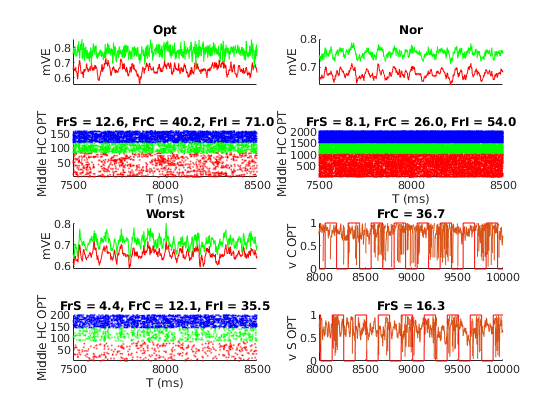

OptE = [L6SFilt>0.9*max(L6SFilt);  L6CFilt>0.9*max(L6CFilt)]';
OptI =  L6IFilt'>0.9*max(L6IFilt);
WorstE = [L6SFilt<1.3*min(L6SFilt);  L6CFilt<1.3*min(L6CFilt)]';
WorstI =  L6IFilt'<1.3*min(L6IFilt);
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColS = NnS.X>=1*n_S_HC & NnS.X<=2*n_S_HC;
MidRowS = NnS.Y>=1*n_S_HC & NnS.Y<=2*n_S_HC;
MidHCS = MidColS & MidRowS;
MidColC = NnC.X>=1*n_C_HC & NnC.X<=2*n_C_HC;
MidRowC = NnC.Y>=1*n_C_HC & NnC.Y<=2*n_C_HC;
MidHCC = MidColC & MidRowC;
MidHCE = [MidHCS, MidHCC];

MidColI = NnI.X>=1*n_I_HC & NnI.X<=2*n_I_HC;
MidRowI = NnI.Y>=1*n_I_HC & NnI.Y<=2*n_I_HC;
MidHCI= MidColI & MidRowI;

% SOpt = find(OptE & ~EcplxInd);
% scatterSOpt = find(ismember(SpE(:,1), SOpt));
% [~,SOpt_Ind] = ismember(SpE(scatterSOpt,1),scatterSOpt);
% FrSOpt = length(SpE(scatterSOpt,2))/(T/1e3)/length(SOpt);
%
% COpt = find(OptE & EcplxInd);
% scatterCOpt = find(ismember(SpE(:,1), COpt));
% [~,COpt_Ind] = ismember(SpE(scatterCOpt,1),scatterCOpt);
% FrCOpt = length(SpE(scatterCOpt,2))/(T/1e3)/length(COpt);

ShowWin = [7500 8500];
figure('Name','Domain Range')
OD1E = find(OptE & MidHCE);
OD1S = find(OptE & MidHCE & (~EcplxInd));
OD1C = find(OptE & MidHCE & (EcplxInd));
OD1I = find(OptI & MidHCI);
scatter1S = find(ismember(SpE(:,1),OD1S));
scatter1C = find(ismember(SpE(:,1),OD1C));
scatter1I = find(ismember(SpI(:,1),OD1I));
[~,OD1S_Ind] = ismember(SpE(scatter1S,1),OD1S);
[~,OD1C_Ind] = ismember(SpE(scatter1C,1),OD1C);
[~,OD1I_Ind] = ismember(SpI(scatter1I,1),OD1I);
subplot 423
hold on
scatter(SpE(scatter1S,2),OD1S_Ind,0.5,'r.')
scatter(SpE(scatter1C,2),OD1C_Ind+max(OD1S_Ind),0.5,'g.')
scatter(SpI(scatter1I,2),OD1I_Ind+length(OD1E),0.5,'b.');
FrS1 = length(SpE(scatter1S,2))/(T/1e3)/length(OD1S);
FrC1 = length(SpE(scatter1C,2))/(T/1e3)/length(OD1C);
FrI1 = length(SpI(scatter1I,2))/(T/1e3)/length(OD1I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS1,FrC1,FrI1))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 421
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD1S,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD1C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

OD2E = find(NorE & MidHCE);
OD2S = find(NorE & MidHCE & (~EcplxInd));
OD2C = find(NorE & MidHCE & (EcplxInd));
OD2I = find(NorI & MidHCI);
scatter2S = find(ismember(SpE(:,1),OD2S));
scatter2C = find(ismember(SpE(:,1),OD2C));
scatter2I = find(ismember(SpI(:,1),OD2I));
[~,OD2S_Ind] = ismember(SpE(scatter2S,1),OD2S);
[~,OD2C_Ind] = ismember(SpE(scatter2C,1),OD2C);
[~,OD2I_Ind] = ismember(SpI(scatter2I,1),OD2I);
subplot 424
hold on
scatter(SpE(scatter2S,2),OD2S_Ind,0.5,'r.')
scatter(SpE(scatter2C,2),OD2C_Ind+max(OD2S_Ind),0.5,'g.')
scatter(SpI(scatter2I,2),OD2I_Ind+length(OD2E),0.5,'b.');
FrS2 = length(SpE(scatter2S,2))/(T/1e3)/length(OD2S);
FrC2 = length(SpE(scatter2C,2))/(T/1e3)/length(OD2C);
FrI2 = length(SpI(scatter2I,2))/(T/1e3)/length(OD2I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS2,FrC2,FrI2))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 422
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD2E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD2C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Nor')
xlim(ShowWin)

OD3E = find(WorstE & MidHCE);
OD3S = find(WorstE & MidHCE & (~EcplxInd));
OD3C = find(WorstE & MidHCE & (EcplxInd));
OD3I = find(WorstI & MidHCI);
scatter3S = find(ismember(SpE(:,1),OD3S));
scatter3C = find(ismember(SpE(:,1),OD3C));
scatter3I = find(ismember(SpI(:,1),OD3I));
[~,OD3S_Ind] = ismember(SpE(scatter3S,1),OD3S);
[~,OD3C_Ind] = ismember(SpE(scatter3C,1),OD3C);
[~,OD3I_Ind] = ismember(SpI(scatter3I,1),OD3I);
subplot 427
hold on
scatter(SpE(scatter3S,2),OD3S_Ind,0.5,'r.')
scatter(SpE(scatter3C,2),OD3C_Ind+max(OD3S_Ind),0.5,'g.')
scatter(SpI(scatter3I,2),OD3I_Ind+length(OD3E),0.5,'b.');
FrS3 = length(SpE(scatter3S,2))/(T/1e3)/length(OD3S);
FrC3 = length(SpE(scatter3C,2))/(T/1e3)/length(OD3C);
FrI3 = length(SpI(scatter3I,2))/(T/1e3)/length(OD3I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS3,FrC3,FrI3))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 425
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD3E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD3C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

% subplot 427
% hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
% xlabel('T (ms)'); ylabel('Spike count for all E cells')
% axis tight
% xlim(ShowWin)
% subplot 425
% plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
% ylabel('mVE')
% set(gca,'xtick','')
% xlim(ShowWin)
tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
subplot 426
hold on
NeuInd = OD1C(5);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E1 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrC = %.1f',Fr1E1))
ylabel('v C OPT')
subplot 428
hold on
NeuInd = OD1S(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E2 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrS = %.1f',Fr1E2))
ylabel('v S OPT')

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);

### Plot Spatial maps: Plot

WinSize = 9000;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));


Determine On and Off t for Frs and mVs: 

Note, we get rid of the first 10ms of each interval

tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
PhaseExc = 20;
mVPh = mod(repmat(PhaseE, 1, WinNum) + repmat(tCorrect(1:end-1), N_E, 1), tMod);
OnOffmV = ~logical(floor(mVPh/MaxOnPhase)); % 1 for all on period, 0 for all off
OnmV  =  OnOffmV & ~(0< mVPh & mVPh<PhaseExc);
OffmV = ~OnOffmV & ~(MaxOnPhase< mVPh & mVPh<MaxOnPhase+PhaseExc);

SpPh = mod(PhaseE(SpE(:,1)) - T + SpE(:,2),tMod);
OnOffSpE =  ~logical(floor(SpPh/MaxOnPhase));
% OnSpE  =  OnOffSpE & ~(0<SpPh & SpPh<PhaseExc);
% OffSpE = ~OnOffSpE & ~(MaxOnPhase<SpPh & SpPh<MaxOnPhase+PhaseExc);
% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

% NnS.X = NnE.X(~EcplxInd); NnS.Y = NnE.Y(~EcplxInd);
% NnC.X = NnE.X(EcplxInd); NnC.Y = NnE.Y(EcplxInd);

FrERan = [0 55];
mVERan = [0.62 0.80];

Figure for ONOFF

First create an onoff vec for each spike

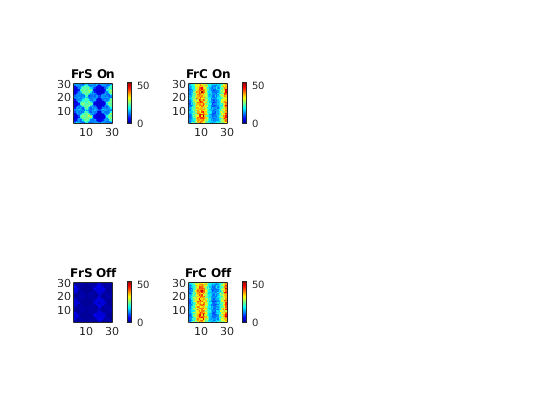

hFrVOnOff = figure('Name','Field_f&V');
% Firing rates:S
subplot 241
ESPinWinOn = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & OnOffSpE;
SpEGoodOn = SpE(ESPinWinOn,1);
[SpCNOn, SpCIOn] = groupcounts(SpEGoodOn);
FrEOn_temp = zeros(N_E,1);
FrEOn_temp(SpCIOn) = SpCNOn*1e3/(EffSize/2);
[FrSOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOnPixMat); title('FrS On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 245
ESPinWinOff = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & ~OnOffSpE;
SpEGoodOff = SpE(ESPinWinOff,1);
[SpCNOff, SpCIOff] = groupcounts(SpEGoodOff);
FrEOff_temp = zeros(N_E,1);
FrEOff_temp(SpCIOff) = SpCNOff*1e3/(EffSize/2);
[FrSOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOffPixMat); title('FrS Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

% Firing rates: C
subplot 242
[FrCOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOnPixMat); title('FrC On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 246
[FrCOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOffPixMat); title('FrC Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar


Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
% % mVs: S
% OnmVPhase = double(OnmV);
% OnmVPhase(~OnmV) = nan;
% mVEOn = mVE; mVEOn = mVEOn.*OnmVPhase;
% mVEOn_temp = nanmean(mVEOn(:,SmallWinRange),2);
% 
% subplot 243
% [mVSOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
% imagesc(mVSOnPixMat); title('mVS On')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; caxis(mVERan)
% 
% OffmVPhase = double(OffmV);
% OffmVPhase(~OffmV) = nan;
% mVEOff = mVE; mVEOff = mVEOff.*OffmVPhase;
% mVEOff_temp = nanmean(mVEOff(:,SmallWinRange),2);
% 
% subplot 247
% [mVSOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
% imagesc(mVSOffPixMat); title('mVS Off')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; caxis(mVERan)
% 
% % mVs: C
% subplot 244
% [mVCOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
% imagesc(mVCOnPixMat); title('mVC On')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; caxis(mVERan)
% 
% subplot 248
% [mVCOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
% imagesc(mVCOffPixMat); title('mVC Off')
% set(gca,'YDir','normal')
% axis square
% colormap jet
% colorbar; caxis(mVERan)

Figure for All Average

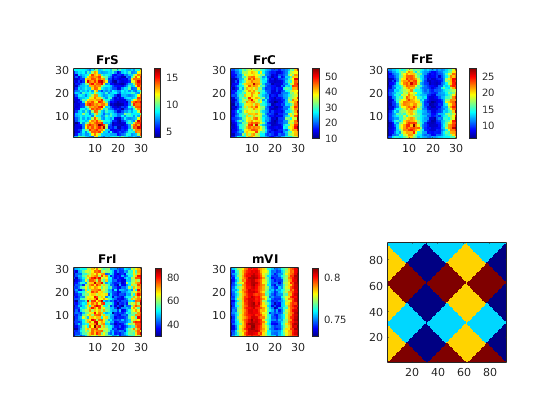

hFrVAll = figure('Name','Field_f&V');
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
%FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

subplot 231
[FrSPixMat,NnSPixel] = NeuVec2Pixel(FrE_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSPixMat); title('FrS')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar
subplot 232
[FrCPixMat,NnCPixel] = NeuVec2Pixel(FrE_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCPixMat); title('FrC')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 233
imagesc(FrSPixMat*(1-CplxR)+ FrCPixMat*CplxR);
title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

% Orientation domain
% subplot 233
% imagesc(OD_EMap);axis square
% set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

Complex % Simple spikes

% end of 500ms plot
OPTC = find(OD_E == 1 & EcplxInd);
OPTS = find(OD_E == 1 & ~EcplxInd);
WORST = find(OD_E == 3);
MID = find(OD_E == 2 | OD_E == 4);
hSpCount = figure('Name','SpCountE')

hSpCount =   Figure (29: SpCountE) with properties:

      Number: 29
        Name: 'SpCountE'
       Color: [0.9400 0.9400 0.9400]
    Position: [1761 1399 560 420]
       Units: 'pixels'

  Show all properties


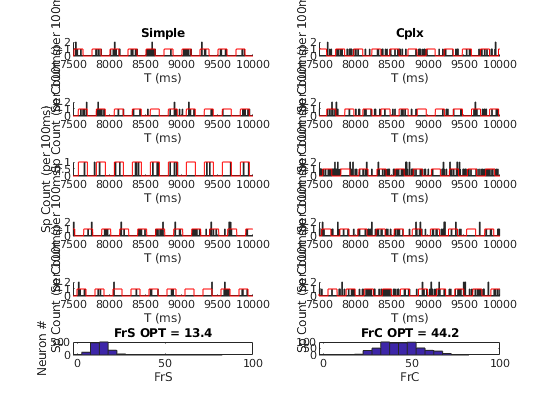

USE = [1,50,300,1000 1500];
for subInd = 1:5
    subplot(6,2,2*subInd-1)
    NeuInd = OPTS(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    if subInd ==1
        title('Simple')
    end

    subplot(6,2,2*subInd)
    NeuInd = OPTC(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')

    if subInd ==1
        title('Cplx')
    end

end
OPTS = OptE & ~EcplxInd;
OPTC = OptE & EcplxInd;
subplot(6,2,11)
hist(FrE_temp(OPTS),0:5:80)
title(sprintf('FrS OPT = %.1f', mean(FrE_temp(OPTS))))
xlabel('FrS'); ylabel('Neuron #')
subplot(6,2,12)
hist(FrE_temp(OPTC),0:5:80)
title(sprintf('FrC OPT = %.1f', mean(FrE_temp(OPTC))))
xlabel('FrC')

%save('DriveWkSp.mat')

### A5. MF linear equation for pixels: 1 Matrices

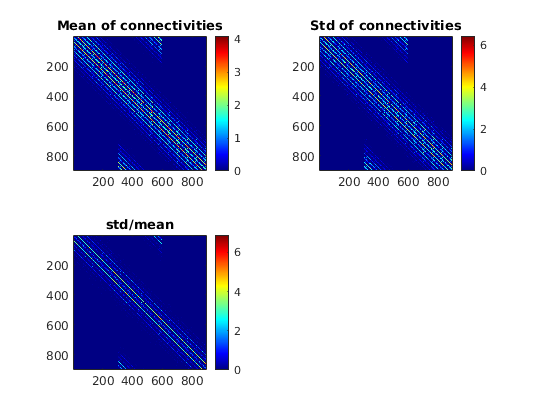

clear ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
    OffmVPhase OnmVPhase OnOffmV OnOffSpE...
    SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood...
    mVE mVEOff mVEOn mVI

load(['ConnPixel_Cconst.mat'])
% Present connectivity mats
figure
subplot 221
imagesc(C_SS_Pixel_Us)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_CS_Pixel_Us)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_CI_Pixel_Us)
axis square
colorbar
title('std/mean')


PixNum = NPixX*N_HC * NPixY*N_HC;
FrSPixVec    = reshape(FrSPixMat,  PixNum,1);
FrSOnPixVec  = reshape(FrSOnPixMat,PixNum,1);
FrSOffPixVec = reshape(FrSOffPixMat,PixNum,1);
FrCPixVec    = reshape(FrCPixMat,  PixNum,1);
FrCOnPixVec  = reshape(FrCOnPixMat,PixNum,1);
FrCOffPixVec = reshape(FrCOffPixMat,PixNum,1);
FrIPixVec    = reshape(FrIPixMat,  PixNum,1);

% mVSOnPixVec  = reshape(mVSOnPixMat,PixNum,1);
% mVSOffPixVec = reshape(mVSOffPixMat,PixNum,1);
% mVCOnPixVec  = reshape(mVCOnPixMat,PixNum,1);
% mVCOffPixVec = reshape(mVCOffPixMat,PixNum,1);
% mVIPixVec = reshape(mVIPixMat,PixNum,1);

% Precompute LGN and L6
lambda_SOn_Pixel = zeros(PixNum,1);
lambda_SOff_Pixel = zeros(PixNum,1);
lambda_COn_Pixel = zeros(PixNum,1);
lambda_COff_Pixel = zeros(PixNum,1);
L6S_Pixel = zeros(PixNum,1);
L6C_Pixel = zeros(PixNum,1);
L6I_Pixel = zeros(PixNum,1);
lambda_SOn_drive = lambda_EOn_drive(~EcplxInd); lambda_COn_drive = lambda_EOn_drive(EcplxInd);
lambda_SOff_drive = lambda_EOff_drive(~EcplxInd); lambda_COff_drive = lambda_EOff_drive(EcplxInd);
rS_L6_Drive = rE_L6_Drive(~EcplxInd); rC_L6_Drive = rE_L6_Drive(EcplxInd);
for PixInd = 1:PixNum
    lambda_SOn_Pixel(PixInd)  = mean(lambda_SOn_drive(NnSPixel.Vec == PixInd));
    lambda_SOff_Pixel(PixInd) = mean(lambda_SOff_drive(NnSPixel.Vec == PixInd));
    lambda_COn_Pixel(PixInd)  = mean(lambda_COn_drive(NnCPixel.Vec == PixInd));
    lambda_COff_Pixel(PixInd) = mean(lambda_COff_drive(NnCPixel.Vec == PixInd));
    L6S_Pixel(PixInd) = mean(rS_L6_Drive(NnSPixel.Vec == PixInd));
    L6C_Pixel(PixInd) = mean(rC_L6_Drive(NnCPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive_Pre;

Below need work

% Setup preused Firing rates for off E
%FrPreUseDim = find(lambda_EOff_Pixel<0.08) + PixNum;
FrPreUseDim = (1:PixNum) + 2*PixNum;
FrPreUse = FrSOffPixVec(FrPreUseDim - 2*PixNum);
%FrPreUse = FrEOffLIF(FrPreUseDim - PixNum);
FrPreUse = [];

### A6. Clear redundant variables for memory

clear C_EE C_EE_Fix_Bd C_EI C_EI_Fix_Bd...
    C_IE C_IE_Fix_Bd C_II C_II_Fix_Bd...
    C_SS_Fix_Bd C_SC_Fix_Bd C_CS_Fix_Bd C_CC_Fix_Bd...
    C_SI_Fix_Bd C_CI_Fix_Bd C_IS_Fix_Bd C_IC_Fix_Bd...
    COpt_Ind SOpt_Ind scatterCOpt scatterSOpt...
    ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
    OffmVPhase OnmVPhase OnOffmV OnOffSpE OnmV OffmV...
    SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood SpPh...
    mVE mVEOff mVEOn mVI ...
    NWTrace AmbE_Events AdjlgnE AmbI_Events CMatAll ...
    EampaInp EnmdaInp GE_ETemp GE_ITemp IampaInp InmdaInp ...
    L6E_Events L6I_Events lgnE_Events lgnI_Events...
    mVECurrent mVICurrent mVETemp mVPh
save([SaveFolder,'AllMFPixPara_Paper2TuneFig1V5D1.mat'])